%作成：2018/09/26-----------------------------------------------------------------------------------
%最短経路長の各素子ペアにおける個々の経路に関して，各媒質の専有面積比から算出した
%平均音速を配列v(送信素子番号,媒質番号,周波数)に格納するスクリプト．
%------------------------------------------------------------------------------------------------------
clear;close all
load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/result/2018_09_08_variousFrequency/statistics.mat",'tof_cell')
load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/param/param_2board.mat")
load("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\statistics.mat",'frq')

## 初期設定

t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
[r_num,t_num,model_num,freq_num] = size(tof_cell);
leng = zeros(r_num,t_num);
for i = 1:r_num
    for j = 1:t_num
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end

## lt(=v)データの作成

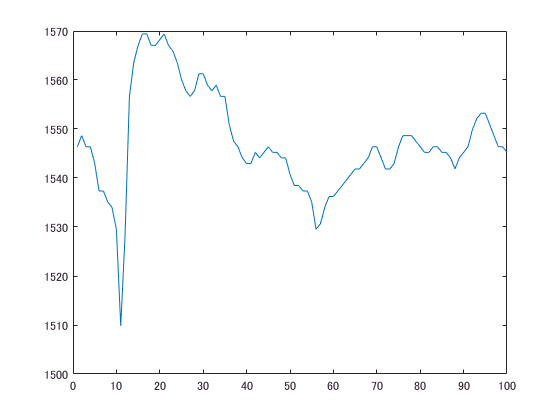

v = zeros(t_num,model_num,freq_num);
for ii = 1:freq_num
    for jj = 1:model_num
        for kk = 1:t_num
            v(kk,jj,ii) = leng(100+kk,kk)/tof_cell(100+kk,kk,jj,ii);
        end
    end
end
figure;
plot(v(:,1,2));

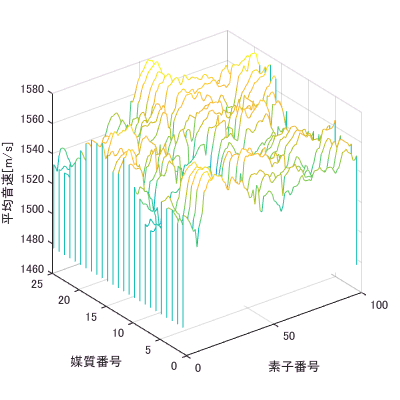

figure;
waterfall(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
zlabel('平均音速[m/s]')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_signal_waterfall",'png',[400,400])

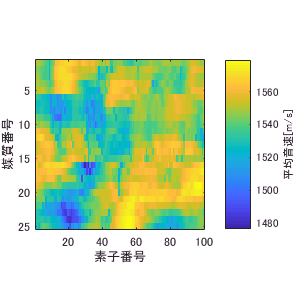

figure;
imagesc(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
axis tight
axis square
c = colorbar;
c.Label.String = '平均音速[m/s]';
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_signal_imagesc",'png',[300,300])

## 参照用のlt(=v)データの作成

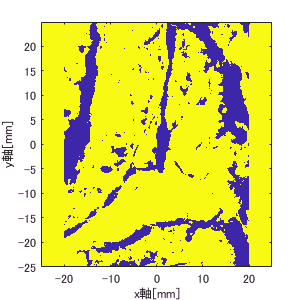

v_reference = zeros(t_num,model_num);
% 適切な参照範囲を探す．
displace_t_m = abs(t_pos(1,2) - t_pos(1,1));%[m]
displace_t = displace_t_m / param.grid.dx;%[t_num]
% 一素子につきグリッド2個分の画素値を平均化して参照用のlt(=v)データの作成を行う．
load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case1.mat")
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
ax = gca;
ax.YDir = 'normal';
xlabel('x軸[mm]')
ylabel('y軸[mm]')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\medium_case1",'png',[300,300]);

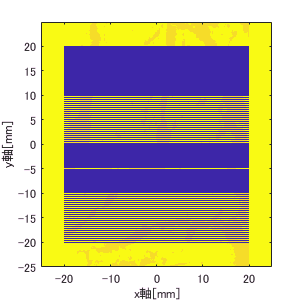

%  素子がどのグリッドに位置しているかを求める．
ind_t_pos = zeros(2,200);
[~,ind_t_pos(1,:)] = min(abs(t_pos(1,:)-kgrid.y_vec));
[~,ind_t_pos(2,:)] = min(abs(t_pos(2,:)-kgrid.x_vec));
ref_medium = medium;
%どのグリッドを参照して参照用のltデータを作成しているかを確認する．また，試行的に一番目のモデルに関して参照用のデータを作成する．
for i = 1:t_num
    v_reference(i,1) = mean2(ref_medium.sound_speed(ind_t_pos(1,i)-1:ind_t_pos(1,i)+1,ind_t_pos(2,100+i):ind_t_pos(2,i)));
    ref_medium.sound_speed(ind_t_pos(1,i)-1:ind_t_pos(1,i)+1,ind_t_pos(2,100+i):ind_t_pos(2,i)) = 0;
end
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,ref_medium.sound_speed);
ax = gca;
ax.YDir = 'normal';
xlabel('x軸[mm]')
ylabel('y軸[mm]')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\refer_range_medium_case1",'png',[300,300]);

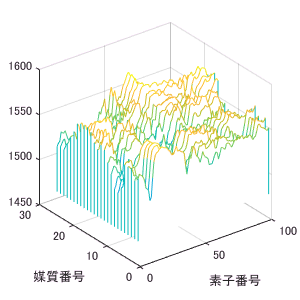

v_reference = zeros(t_num,model_num);
% 画素値平均化を行う
for jj = 1:model_num
    loadfilename = sprintf("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case%d.mat",jj);
    load(loadfilename);
    ref_medium = medium;
    for ii = 1:t_num
        v_reference(ii,jj) = mean2(ref_medium.sound_speed(ind_t_pos(1,ii)-1:ind_t_pos(1,ii)+1,ind_t_pos(2,100+ii):ind_t_pos(2,ii)));
    end
end
v_reference = repmat(v_reference,1,1,6);
figure;
waterfall(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_medium_waterfall_2MHz",'png',[300,300]);

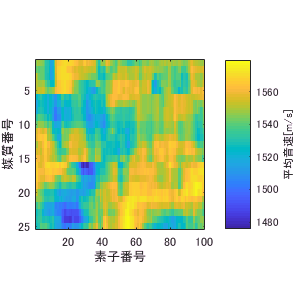

figure;
imagesc(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
axis tight
axis square
c = colorbar;
c.Label.String = '平均音速[m/s]';
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_medium_imagesc_2MHz",'png',[300,300])

## vプロットの比較(プロット編)

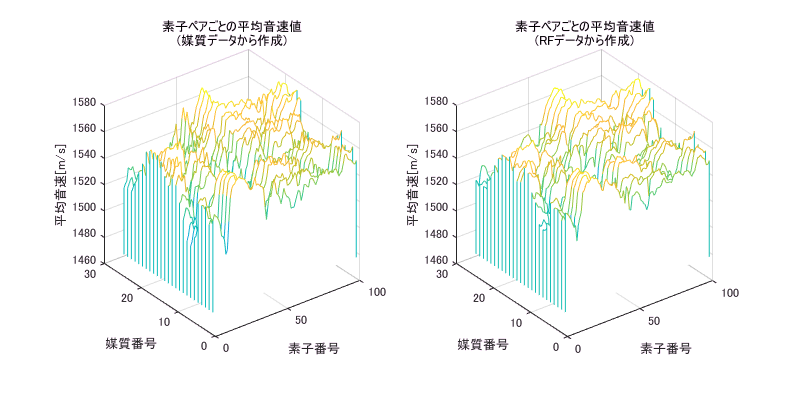

%water-fallプロット
figure;
subplot(1,2,1);
waterfall(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
zlabel('平均音速[m/s]')
title({'素子ペアごとの平均音速値';'(媒質データから作成)'})
axis square
subplot(1,2,2);
waterfall(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
zlabel('平均音速[m/s]')
title({'素子ペアごとの平均音速値';'(RFデータから作成)'})
axis square
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_compared_waterfall_2MHz",'png',[800,400])

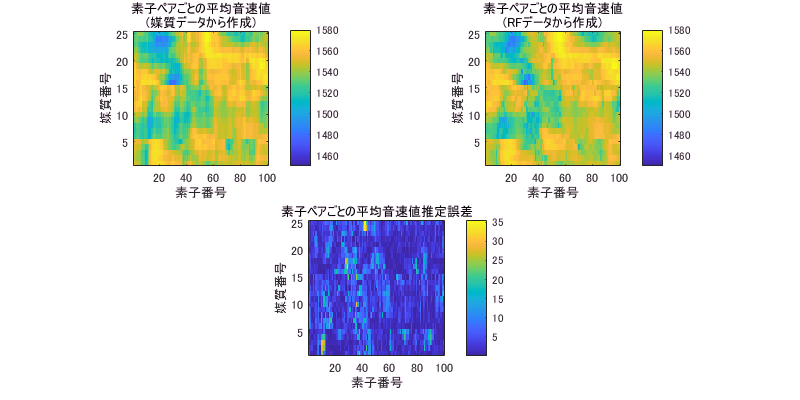

%imagescプロット
figure;
subplot(2,2,1);
imagesc(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
title({'素子ペアごとの平均音速値';'(媒質データから作成)'})
axis square
colorbar
caxis([1450 1580])
ax = gca;
ax.YDir = 'normal';
subplot(2,2,2);
imagesc(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
title({'素子ペアごとの平均音速値';'(RFデータから作成)'})
axis square
colorbar
caxis([1450 1580])
ax = gca;
ax.YDir = 'normal';
subplot(2,2,[3,4]);
imagesc(abs(v(:,:,1)'-v_reference(:,:,1)'));
xlabel('素子番号')
ylabel('媒質番号')
title('素子ペアごとの平均音速値推定誤差')
axis square
colorbar
ax = gca;
ax.YDir = 'normal';
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_compared_imagesc_2MHz",'png',[800,400])

## ｖプロットの比較（統計編）　※Rは使用しない．

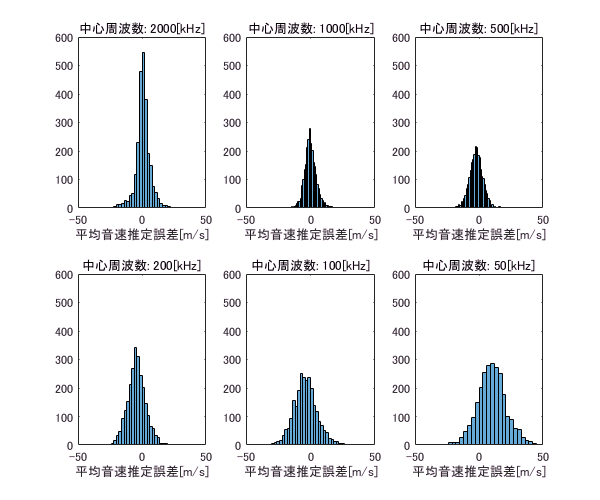

v_error = zeros(2500,6);%(vサンプル数，周波数条件数)
v_error_var = zeros(1,6);%(1,周波数条件数)
for ii = 1:6
    error = (v(:,:,ii)' - v_reference(:,:,ii)');
    error = reshape(error,1,2500);
    v_error_var(1,ii) = var(error);
    subplot(2,3,ii);
    histogram(error,'BinMethod','scott');
    titlename = sprintf('中心周波数: %d[kHz]',frq(ii,1)/1000);
    title(titlename);
    xlabel('平均音速推定誤差[m/s]')
    xlim([-50 50])
    ylim([0 600])
    v_error(:,ii) = error;
end
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_error_histogram_scott",'png',[600,500])

## 参照用のlt(=v)データの作成(2)―参照グリッド拡大

v_reference = zeros(t_num,model_num);
% 適切な参照範囲を探す．
displace_t_m = abs(t_pos(1,2) - t_pos(1,1));%[m]
displace_t = displace_t_m / param.grid.dx;%[t_num]
% 一素子につきグリッド2個分の画素値を平均化して参照用のlt(=v)データの作成を行う．
load("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case1.mat")
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
ax = gca;
ax.YDir = 'normal';
xlabel('x軸[mm]')
ylabel('y軸[mm]')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\medium_case1",'png',[300,300]);

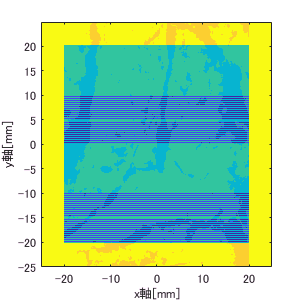

%  素子がどのグリッドに位置しているかを求める．
ind_t_pos = zeros(2,200);
[~,ind_t_pos(1,:)] = min(abs(t_pos(1,:)-kgrid.y_vec));
[~,ind_t_pos(2,:)] = min(abs(t_pos(2,:)-kgrid.x_vec));
ref_medium = medium;
%どのグリッドを参照して参照用のltデータを作成しているかを確認する．また，試行的に一番目のモデルに関して参照用のデータを作成する．
for i = 1:t_num
    v_reference(i,1) = mean2(ref_medium.sound_speed(ind_t_pos(1,i)-2:ind_t_pos(1,i)+2,ind_t_pos(2,100+i):ind_t_pos(2,i)));
    ref_medium.sound_speed(ind_t_pos(1,i)-2:ind_t_pos(1,i)+2,ind_t_pos(2,100+i):ind_t_pos(2,i)) = ref_medium.sound_speed(ind_t_pos(1,i)-2:ind_t_pos(1,i)+2,ind_t_pos(2,100+i):ind_t_pos(2,i))-500;
end
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,ref_medium.sound_speed);
ax = gca;
ax.YDir = 'normal';
xlabel('x軸[mm]')
ylabel('y軸[mm]')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\refer_range_medium_case1_wider",'png',[300,300]);

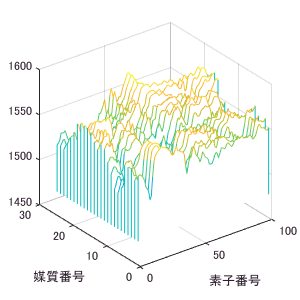

v_reference = zeros(t_num,model_num);
% 画素値平均化を行う
for jj = 1:model_num
    loadfilename = sprintf("//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter/case%d.mat",jj);
    load(loadfilename);
    ref_medium = medium;
    for ii = 1:t_num
        v_reference(ii,jj) = mean2(ref_medium.sound_speed(ind_t_pos(1,ii)-2:ind_t_pos(1,ii)+2,ind_t_pos(2,100+ii):ind_t_pos(2,ii)));
    end
end
v_reference = repmat(v_reference,1,1,6);
figure;
waterfall(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_medium_waterfall_2MHz_wider",'png',[300,300]);

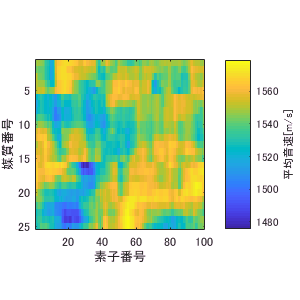

figure;
imagesc(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
axis tight
axis square
c = colorbar;
c.Label.String = '平均音速[m/s]';
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_from_medium_imagesc_2MHz_wider",'png',[300,300])

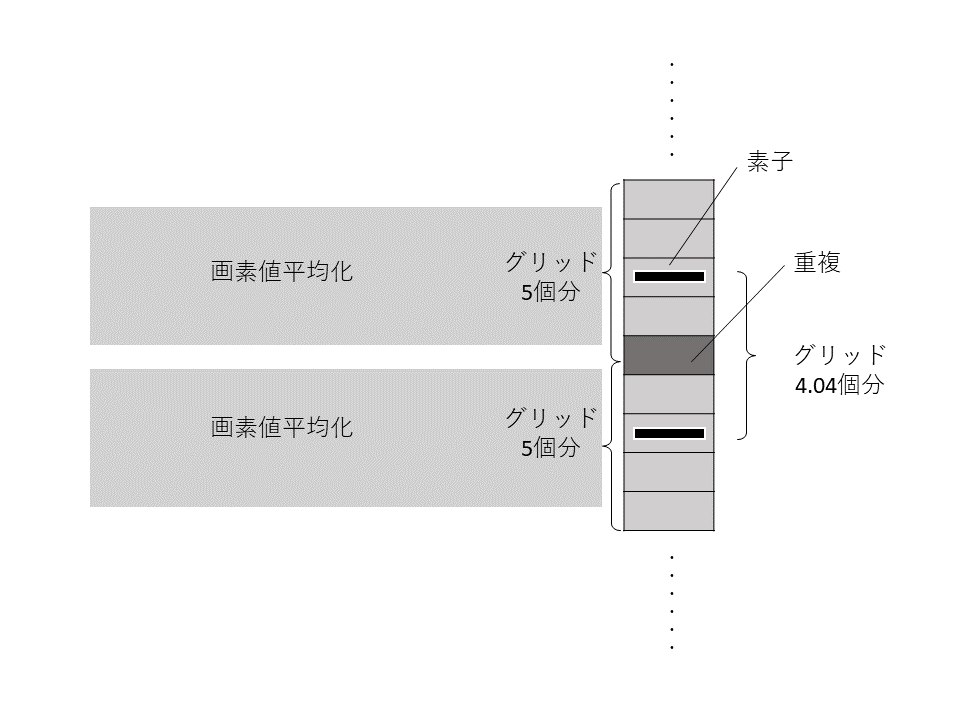

## vプロットの比較(プロット編)

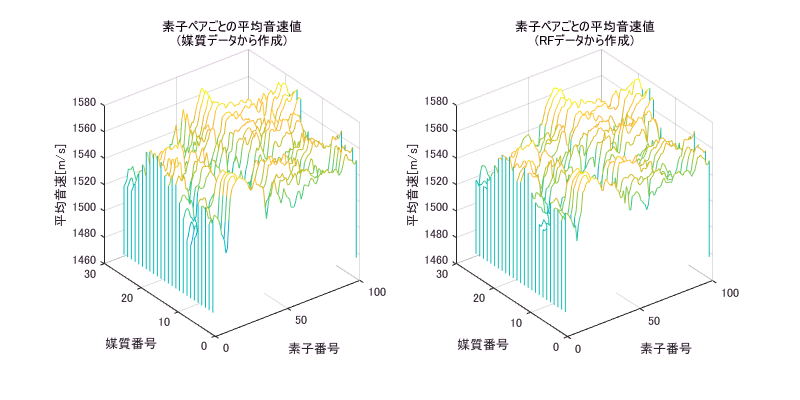

%water-fallプロット
figure;
subplot(1,2,1);
waterfall(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
zlabel('平均音速[m/s]')
title({'素子ペアごとの平均音速値';'(媒質データから作成)'})
axis square
subplot(1,2,2);
waterfall(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
zlabel('平均音速[m/s]')
title({'素子ペアごとの平均音速値';'(RFデータから作成)'})
axis square
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_compared_waterfall_2MHz_wider",'png',[800,400])

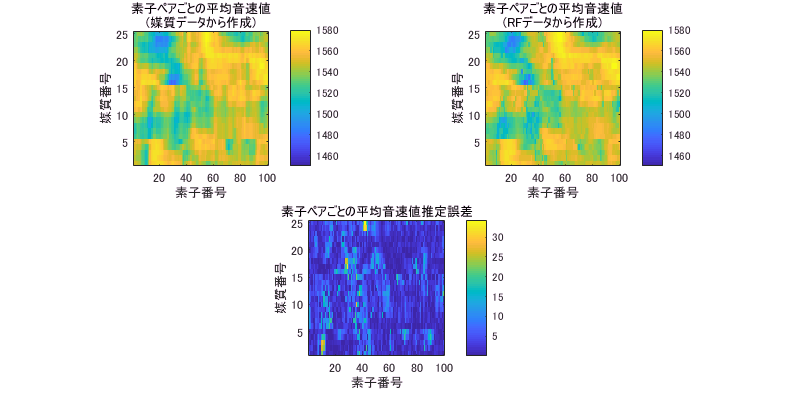

%imagescプロット
figure;
subplot(2,2,1);
imagesc(v_reference(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
title({'素子ペアごとの平均音速値';'(媒質データから作成)'})
axis square
colorbar
caxis([1450 1580])
ax = gca;
ax.YDir = 'normal';
subplot(2,2,2);
imagesc(v(:,:,1)');
xlabel('素子番号')
ylabel('媒質番号')
title({'素子ペアごとの平均音速値';'(RFデータから作成)'})
axis square
colorbar
caxis([1450 1580])
ax = gca;
ax.YDir = 'normal';
subplot(2,2,[3,4]);
imagesc(abs(v(:,:,1)'-v_reference(:,:,1)'));
xlabel('素子番号')
ylabel('媒質番号')
title('素子ペアごとの平均音速値推定誤差')
axis square
colorbar
ax = gca;
ax.YDir = 'normal';
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_compared_imagesc_2MHz_wider",'png',[800,400])

## ｖプロットの比較（統計編）　※Rは使用しない．

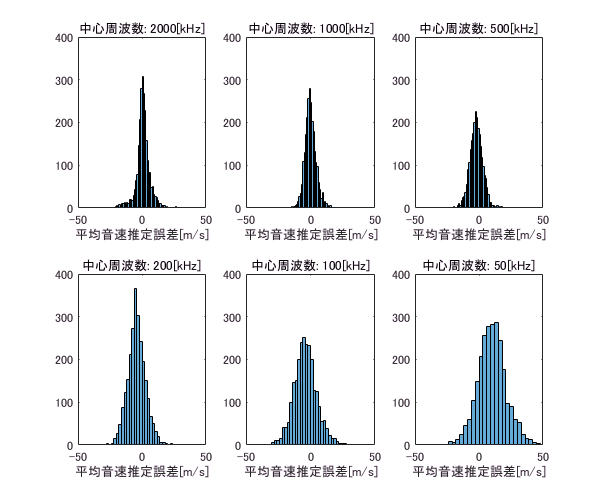

v_error = zeros(2500,6);%(vサンプル数，周波数条件数)
v_error_var = zeros(1,6);%(1,周波数条件数)
for ii = 1:6
    error = (v(:,:,ii)' - v_reference(:,:,ii)');
    error = reshape(error,1,2500);
    v_error_var(1,ii) = var(error);
    subplot(2,3,ii);
    histogram(error,'BinMethod','scott');
    titlename = sprintf('中心周波数: %d[kHz]',frq(ii,1)/1000);
    title(titlename);
    xlabel('平均音速推定誤差[m/s]')
    xlim([-50 50])
    ylim([0 400])
    v_error(:,ii) = error;
end
exportfig("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_09_26_ltplot\lt_error_histogram_scott_wider",'png',[600,500])

## 経路変化分の分散値などを参考にして媒質データから平均音速値を算出するときの計算領域を設定するのが良さそうではあるが，とりあえずグリッド５個分参照した結果をもとに解析する．

csvwrite("\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\v_error.csv",v_error);